状态空间方程

Gs_ss_1 = series(Gns_ss,Hs1*k6);
Gs_ss_2 = series(Gs_ss_1,Ds_ss);
Gs_ss_3 = series(Gs_ss_2,k4*Hs2);

ss形式，连续

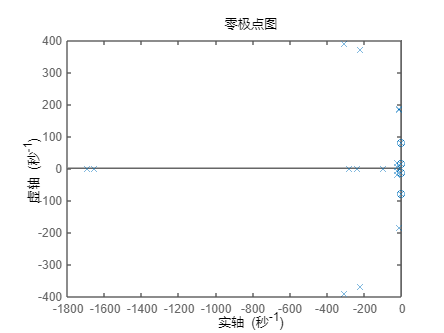

Gcl_ss = feedback(Gs_ss_3,Gps_tf);
pzmap(Gcl_ss)

ss形式，离散

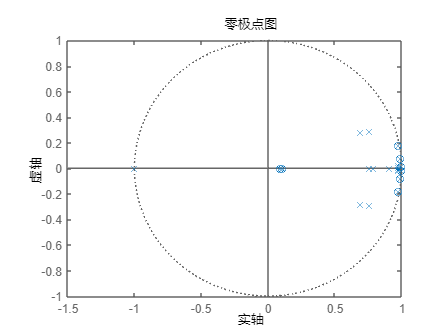

Gcld_ss = c2d(Gcl_ss,dt,'tustin');
pzmap(Gcld_ss)

传递函数

%Gs_tf_1 = k4*Hs2*G1_tfd*Hs1*k6*Gnd_tf;
%Gcl = (eye(5)+Gp_tf*Gs_tf_1)\(Gp_tf*Gs_tf_1);

tf形式，连续

Gcl_tf = tf(minreal(Gcl_ss));

202 states removed.


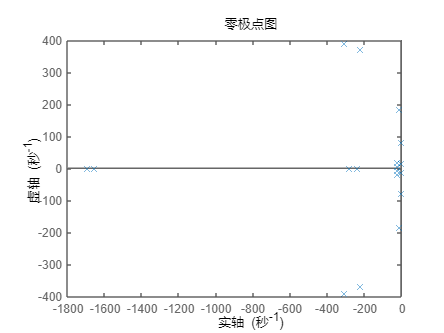

pzmap(Gcl_tf)

tf形式离散

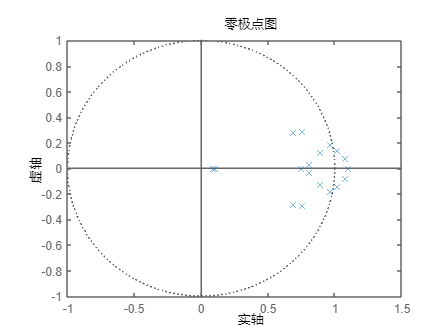

Gcld_tf = c2d(Gcl_tf,dt,'tustin');
pzmap(Gcld_tf)